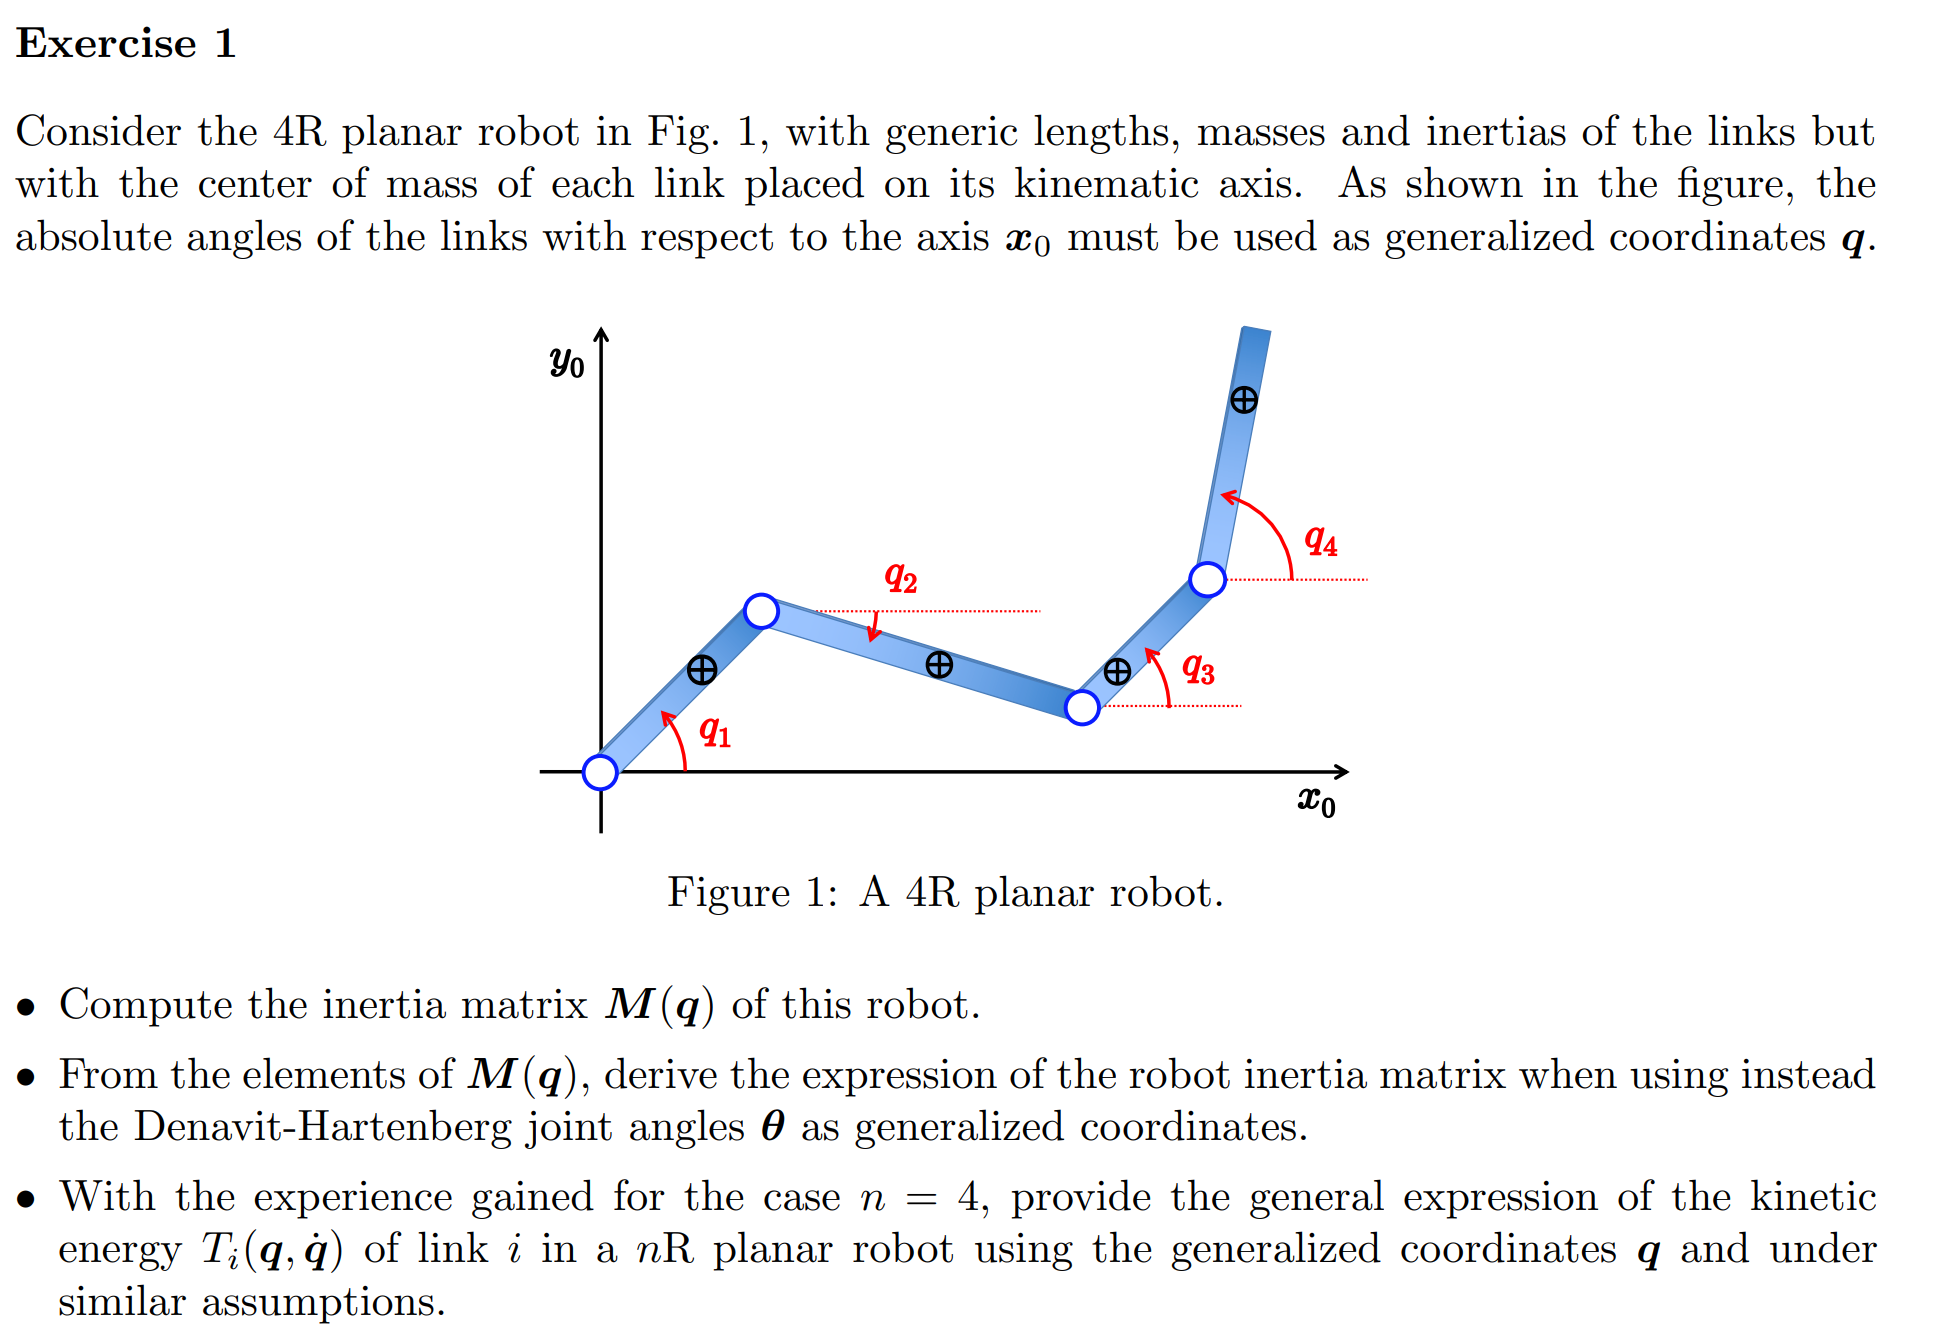

syms q1 q2 q3 q4 q_dot_1 q_dot_2 q_dot_3 q_dot_4 real
syms  m_1 m_2 m_3 m_4 I_1 I_2 I_3 I_4 l_1 l_2 l_3 l_4 g0 positive
syms d_1 d_2 d_3 d_4 real
 
% Dynamic model
% joint 1 
x1 = d_1*cos(q1);
y1 = d_1*sin(q1);

vx1 = diff(x1,q1)*q_dot_1 + diff(x1,q2)*q_dot_2 + diff(x1,q3)*q_dot_3 + diff(x1,q4)*q_dot_4

$$vx1 = -d_{1}\,{\dot{q}}_{1}\,\sin\left(q_{1}\right)$$

vy1 = diff(y1,q1)*q_dot_1 + diff(y1,q2)*q_dot_2 + diff(y1,q3)*q_dot_3 + diff(y1,q4)*q_dot_4

$$vy1 = d_{1}\,{\dot{q}}_{1}\,\cos\left(q_{1}\right)$$


T1_tr = 0.5*m_1*[vx1 vy1]*[vx1; vy1;];
T1_rot = 0.5*I_1*[0 0 q_dot_1]*[0; 0; q_dot_1;];
T1 = simplify(T1_tr + T1_rot)

$$T1 = \frac{{{\dot{q}}_{1}}^{2}\,\left(m_{1}\,{d_{1}}^{2}+I_{1}\right)}{2}$$


% joint 2 
x2 = l_1*cos(q1)+d_2*cos(q2);
y2 = l_1*sin(q1)+d_2*sin(q2);

vx2 = diff(x2,q1)*q_dot_1 + diff(x2,q2)*q_dot_2 + diff(x2,q3)*q_dot_3 + diff(x2,q4)*q_dot_4

$$vx2 = -d_{2}\,{\dot{q}}_{2}\,\sin\left(q_{2}\right)-l_{1}\,{\dot{q}}_{1}\,\sin\left(q_{1}\right)$$

vy2 = diff(y2,q1)*q_dot_1 + diff(y2,q2)*q_dot_2 + diff(y2,q3)*q_dot_3 + diff(y2,q4)*q_dot_4

$$vy2 = d_{2}\,{\dot{q}}_{2}\,\cos\left(q_{2}\right)+l_{1}\,{\dot{q}}_{1}\,\cos\left(q_{1}\right)$$


T2_tr = 0.5*m_2*[vx2 vy2]*[vx2; vy2;];
T2_rot = 0.5*I_2*[0 0 q_dot_2]*[0; 0; q_dot_2;];
T2 = T2_tr + T2_rot

$$T2 = \frac{I_{2}\,{{\dot{q}}_{2}}^{2}}{2}+\frac{m_{2}\,{\left(d_{2}\,{\dot{q}}_{2}\,\cos\left(q_{2}\right)+l_{1}\,{\dot{q}}_{1}\,\cos\left(q_{1}\right)\right)}^{2}}{2}+\frac{m_{2}\,{\left(d_{2}\,{\dot{q}}_{2}\,\sin\left(q_{2}\right)+l_{1}\,{\dot{q}}_{1}\,\sin\left(q_{1}\right)\right)}^{2}}{2}$$


% joint 3
x3 = l_1*cos(q1)+l_2*cos(q2)+d_3*cos(q3);
y3 = l_1*sin(q1)+l_2*sin(q2)+d_3*sin(q3);

vx3 = diff(x3,q1)*q_dot_1 + diff(x3,q2)*q_dot_2 + diff(x3,q3)*q_dot_3 + diff(x3,q4)*q_dot_4;
vy3 = diff(y3,q1)*q_dot_1 + diff(y3,q2)*q_dot_2 + diff(y3,q3)*q_dot_3 + diff(y3,q4)*q_dot_4;

T3_tr = 0.5*m_3*[vx3 vy3]*[vx3; vy3;];
T3_rot = 0.5*I_3*[0 0 q_dot_3]*[0; 0; q_dot_3;];
T3 = T3_tr + T3_rot

$$T3 = \frac{I_{3}\,{{\dot{q}}_{3}}^{2}}{2}+\frac{m_{3}\,{\left(d_{3}\,{\dot{q}}_{3}\,\cos\left(q_{3}\right)+l_{1}\,{\dot{q}}_{1}\,\cos\left(q_{1}\right)+l_{2}\,{\dot{q}}_{2}\,\cos\left(q_{2}\right)\right)}^{2}}{2}+\frac{m_{3}\,{\left(d_{3}\,{\dot{q}}_{3}\,\sin\left(q_{3}\right)+l_{1}\,{\dot{q}}_{1}\,\sin\left(q_{1}\right)+l_{2}\,{\dot{q}}_{2}\,\sin\left(q_{2}\right)\right)}^{2}}{2}$$


% joint 4
x4 = l_1*cos(q1)+l_2*cos(q2)+l_3*cos(q3)+d_4*cos(q4);
y4 = l_1*sin(q1)+l_2*sin(q2)+l_3*sin(q3)+d_4*sin(q4);

vx4 = diff(x4,q1)*q_dot_1 + diff(x4,q2)*q_dot_2 + diff(x4,q3)*q_dot_3 + diff(x4,q4)*q_dot_4;
vy4 = diff(y4,q1)*q_dot_1 + diff(y4,q2)*q_dot_2 + diff(y4,q3)*q_dot_3 + diff(y4,q4)*q_dot_4;

T4_tr = 0.5*m_4*[vx4 vy4]*[vx4; vy4;];
T4_rot = 0.5*I_4*[0 0 q_dot_4]*[0; 0; q_dot_4;];
T4 = T4_tr + T4_rot

$$T4 = \frac{m_{4}\,{\left(d_{4}\,{\dot{q}}_{4}\,\sin\left(q_{4}\right)+l_{1}\,{\dot{q}}_{1}\,\sin\left(q_{1}\right)+l_{2}\,{\dot{q}}_{2}\,\sin\left(q_{2}\right)+l_{3}\,{\dot{q}}_{3}\,\sin\left(q_{3}\right)\right)}^{2}}{2}+\frac{I_{4}\,{{\dot{q}}_{4}}^{2}}{2}+\frac{m_{4}\,{\left(d_{4}\,{\dot{q}}_{4}\,\cos\left(q_{4}\right)+l_{1}\,{\dot{q}}_{1}\,\cos\left(q_{1}\right)+l_{2}\,{\dot{q}}_{2}\,\cos\left(q_{2}\right)+l_{3}\,{\dot{q}}_{3}\,\cos\left(q_{3}\right)\right)}^{2}}{2}$$


% Total Energy
T = T1+T2+T3+T4

$$T = \begin{array}{l} \frac{m_{4}\,{\left(d_{4}\,{\dot{q}}_{4}\,\sin\left(q_{4}\right)+\sigma_{1}+\sigma_{3}+l_{3}\,{\dot{q}}_{3}\,\sin\left(q_{3}\right)\right)}^{2}}{2}+\frac{{{\dot{q}}_{1}}^{2}\,\left(m_{1}\,{d_{1}}^{2}+I_{1}\right)}{2}+\frac{I_{2}\,{{\dot{q}}_{2}}^{2}}{2}+\frac{I_{3}\,{{\dot{q}}_{3}}^{2}}{2}+\frac{I_{4}\,{{\dot{q}}_{4}}^{2}}{2}+\frac{m_{2}\,{\left(d_{2}\,{\dot{q}}_{2}\,\cos\left(q_{2}\right)+\sigma_{2}\right)}^{2}}{2}+\frac{m_{3}\,{\left(d_{3}\,{\dot{q}}_{3}\,\cos\left(q_{3}\right)+\sigma_{2}+\sigma_{4}\right)}^{2}}{2}+\frac{m_{2}\,{\left(d_{2}\,{\dot{q}}_{2}\,\sin\left(q_{2}\right)+\sigma_{1}\right)}^{2}}{2}+\frac{m_{4}\,{\left(d_{4}\,{\dot{q}}_{4}\,\cos\left(q_{4}\right)+\sigma_{2}+\sigma_{4}+l_{3}\,{\dot{q}}_{3}\,\cos\left(q_{3}\right)\right)}^{2}}{2}+\frac{m_{3}\,{\left(d_{3}\,{\dot{q}}_{3}\,\sin\left(q_{3}\right)+\sigma_{1}+\sigma_{3}\right)}^{2}}{2}\\ \mathrm{where}\\ \sigma_{1}=l_{1}\,{\dot{q}}_{1}\,\sin\left(q_{1}\right)\\ \sigma_{2}=l_{1}\,{\dot{q}}_{1}\,\cos\left(q_{1}\right)\\ \sigma_{3}=l_{2}\,{\dot{q}}_{2}\,\sin\left(q_{2}\right)\\ \sigma_{4}=l_{2}\,{\dot{q}}_{2}\,\cos\left(q_{2}\right) \end{array}$$


% Inertia Matrix
q_dot = [q_dot_1, q_dot_2, q_dot_3, q_dot_4]; % vettore delle velocità

% Inizializza la matrice di inerzia simbolica 4x4
M = sym(zeros(4));

% Calcolo degli elementi della matrice M a partire da T
for i = 1:4
    for j = 1:4
        M(i,j) = simplify(diff(diff(T, q_dot(i)), q_dot(j)));
    end
end

% Stampa della matrice di inerzia
disp('Inertia Matrix M(q)');

Inertia Matrix M(q)


disp(M);

$$\begin{array}{l} \left(\begin{array}{cccc} I_{1}+{d_{1}}^{2}\,m_{1}+{l_{1}}^{2}\,m_{2}+{l_{1}}^{2}\,m_{3}+{l_{1}}^{2}\,m_{4} & \sigma_{1} & \sigma_{3} & \sigma_{6}\\ \sigma_{1} & I_{2}+{d_{2}}^{2}\,m_{2}+{l_{2}}^{2}\,m_{3}+{l_{2}}^{2}\,m_{4} & \sigma_{2} & \sigma_{5}\\ \sigma_{3} & \sigma_{2} & m_{3}\,{d_{3}}^{2}+m_{4}\,{l_{3}}^{2}+I_{3} & \sigma_{4}\\ \sigma_{6} & \sigma_{5} & \sigma_{4} & m_{4}\,{d_{4}}^{2}+I_{4} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=l_{1}\,\cos\left(q_{1}-q_{2}\right)\,\left(d_{2}\,m_{2}+l_{2}\,m_{3}+l_{2}\,m_{4}\right)\\ \sigma_{2}=l_{2}\,\cos\left(q_{2}-q_{3}\right)\,\left(d_{3}\,m_{3}+l_{3}\,m_{4}\right)\\ \sigma_{3}=l_{1}\,\cos\left(q_{1}-q_{3}\right)\,\left(d_{3}\,m_{3}+l_{3}\,m_{4}\right)\\ \sigma_{4}=d_{4}\,l_{3}\,m_{4}\,\cos\left(q_{3}-q_{4}\right)\\ \sigma_{5}=d_{4}\,l_{2}\,m_{4}\,\cos\left(q_{2}-q_{4}\right)\\ \sigma_{6}=d_{4}\,l_{1}\,m_{4}\,\cos\left(q_{1}-q_{4}\right) \end{array}$$


% Coordinate simboliche relative (DH)
syms theta_1 theta_2 theta_3 theta_4 real
theta = [theta_1; theta_2; theta_3; theta_4];

% Relazione q = T*theta (angoli assoluti come somma cumulativa dei relativi)
T_rel2abs = [1 0 0 0;
             1 1 0 0;
             1 1 1 0;
             1 1 1 1];

q = T_rel2abs * theta;  % q in funzione di theta

% Sostituisci q -> funzione di theta
M_theta = simplify(subs(M, [q1, q2, q3, q4], q.'));

disp('Inertia Matrix M(theta)');

Inertia Matrix M(theta)


disp(M_theta);

$$\begin{array}{l} \left(\begin{array}{cccc} I_{1}+{d_{1}}^{2}\,m_{1}+{l_{1}}^{2}\,m_{2}+{l_{1}}^{2}\,m_{3}+{l_{1}}^{2}\,m_{4} & \sigma_{1} & \sigma_{5} & \sigma_{2}\\ \sigma_{1} & I_{2}+{d_{2}}^{2}\,m_{2}+{l_{2}}^{2}\,m_{3}+{l_{2}}^{2}\,m_{4} & \sigma_{6} & \sigma_{3}\\ \sigma_{5} & \sigma_{6} & m_{3}\,{d_{3}}^{2}+m_{4}\,{l_{3}}^{2}+I_{3} & \sigma_{4}\\ \sigma_{2} & \sigma_{3} & \sigma_{4} & m_{4}\,{d_{4}}^{2}+I_{4} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=l_{1}\,\cos\left(\theta_{2}\right)\,\left(d_{2}\,m_{2}+l_{2}\,m_{3}+l_{2}\,m_{4}\right)\\ \sigma_{2}=d_{4}\,l_{1}\,m_{4}\,\cos\left(\theta_{2}+\theta_{3}+\theta_{4}\right)\\ \sigma_{3}=d_{4}\,l_{2}\,m_{4}\,\cos\left(\theta_{3}+\theta_{4}\right)\\ \sigma_{4}=d_{4}\,l_{3}\,m_{4}\,\cos\left(\theta_{4}\right)\\ \sigma_{5}=l_{1}\,\cos\left(\theta_{2}+\theta_{3}\right)\,\sigma_{7}\\ \sigma_{6}=l_{2}\,\cos\left(\theta_{3}\right)\,\sigma_{7}\\ \sigma_{7}=d_{3}\,m_{3}+l_{3}\,m_{4} \end{array}$$


app = T_rel2abs.'*M

$$app = \begin{array}{l} \left(\begin{array}{cccc} I_{1}+{d_{1}}^{2}\,m_{1}+{l_{1}}^{2}\,m_{2}+{l_{1}}^{2}\,m_{3}+{l_{1}}^{2}\,m_{4}+\sigma_{6}+\sigma_{1}+\sigma_{4} & I_{2}+{d_{2}}^{2}\,m_{2}+{l_{2}}^{2}\,m_{3}+{l_{2}}^{2}\,m_{4}+\sigma_{5}+\sigma_{1}+\sigma_{2} & I_{3}+{d_{3}}^{2}\,m_{3}+{l_{3}}^{2}\,m_{4}+\sigma_{6}+\sigma_{5}+\sigma_{3} & I_{4}+{d_{4}}^{2}\,m_{4}+\sigma_{4}+\sigma_{2}+\sigma_{3}\\ \sigma_{6}+\sigma_{1}+\sigma_{4} & I_{2}+{d_{2}}^{2}\,m_{2}+{l_{2}}^{2}\,m_{3}+{l_{2}}^{2}\,m_{4}+\sigma_{5}+\sigma_{2} & I_{3}+{d_{3}}^{2}\,m_{3}+{l_{3}}^{2}\,m_{4}+\sigma_{5}+\sigma_{3} & I_{4}+{d_{4}}^{2}\,m_{4}+\sigma_{2}+\sigma_{3}\\ \sigma_{6}+\sigma_{4} & \sigma_{5}+\sigma_{2} & m_{3}\,{d_{3}}^{2}+m_{4}\,{l_{3}}^{2}+d_{4}\,m_{4}\,\cos\left(q_{3}-q_{4}\right)\,l_{3}+I_{3} & m_{4}\,{d_{4}}^{2}+l_{3}\,m_{4}\,\cos\left(q_{3}-q_{4}\right)\,d_{4}+I_{4}\\ \sigma_{4} & \sigma_{2} & \sigma_{3} & m_{4}\,{d_{4}}^{2}+I_{4} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=l_{1}\,\cos\left(q_{1}-q_{2}\right)\,\left(d_{2}\,m_{2}+l_{2}\,m_{3}+l_{2}\,m_{4}\right)\\ \sigma_{2}=d_{4}\,l_{2}\,m_{4}\,\cos\left(q_{2}-q_{4}\right)\\ \sigma_{3}=d_{4}\,l_{3}\,m_{4}\,\cos\left(q_{3}-q_{4}\right)\\ \sigma_{4}=d_{4}\,l_{1}\,m_{4}\,\cos\left(q_{1}-q_{4}\right)\\ \sigma_{5}=l_{2}\,\cos\left(q_{2}-q_{3}\right)\,\sigma_{7}\\ \sigma_{6}=l_{1}\,\cos\left(q_{1}-q_{3}\right)\,\sigma_{7}\\ \sigma_{7}=d_{3}\,m_{3}+l_{3}\,m_{4} \end{array}$$

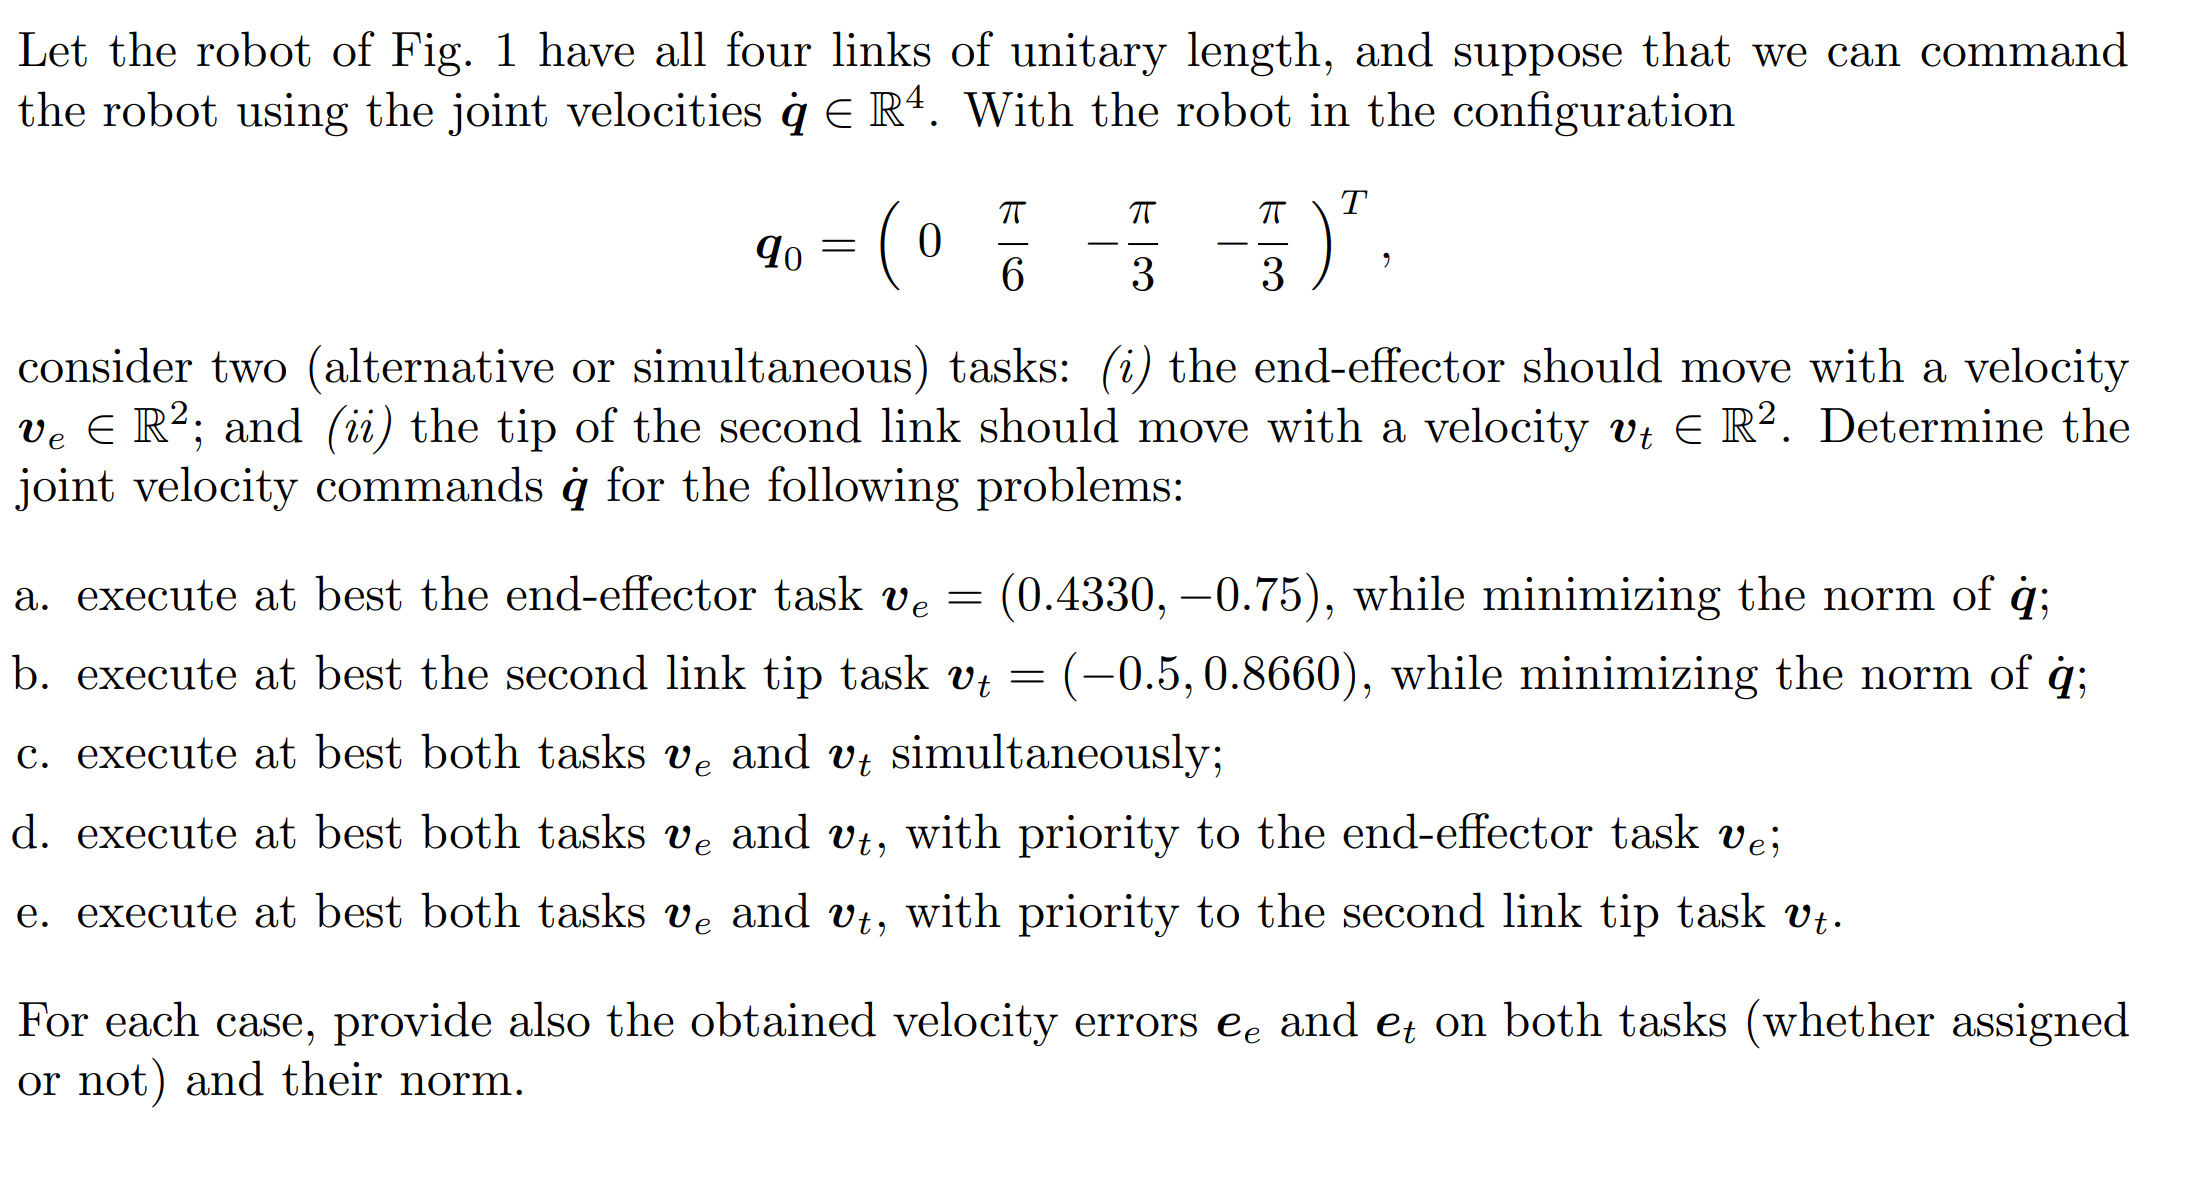

% Parametri simbolici
syms q1 q2 q3 q4 real
q_val = [0, pi/6, -pi/3, -pi/3];

% End-effector
p_e = [cos(q1)+cos(q2)+cos(q3)+cos(q4);
       sin(q1)+sin(q2)+sin(q3)+sin(q4)];
J_e = jacobian(p_e, [q1, q2, q3, q4]);
J_e_num = double(subs(J_e, [q1,q2,q3,q4], q_val));
v_e = [0.4330; -0.75];
qdot_a = pinv(J_e_num)*v_e;
v_e_achieved_a = J_e_num*qdot_a;
e_e_a = v_e - v_e_achieved_a;

% Second link tip
p_t = [cos(q1)+cos(q2);
       sin(q1)+sin(q2)];
J_t = jacobian(p_t, [q1, q2, q3, q4]);
J_t_num = double(subs(J_t, [q1,q2,q3,q4], q_val));
v_t = [-0.5; 0.8660];
qdot_b = pinv(J_t_num)*v_t;
v_t_achieved_b = J_t_num*qdot_b;
e_t_b = v_t - v_t_achieved_b;

% Entrambi i task contemporaneamente
J_stack = [J_e_num; J_t_num];
v_stack = [v_e; v_t];
qdot_c = pinv(J_stack)*v_stack;
e_e_c = v_e - J_e_num*qdot_c;
e_t_c = v_t - J_t_num*qdot_c;

% Priorità a end-effector
qdot_d1 = pinv(J_e_num)*v_e;
P_e = eye(4) - pinv(J_e_num)*J_e_num;
J_t_proj = J_t_num * P_e;
qdot_d2 = pinv(J_t_proj)*(v_t - J_t_num*qdot_d1);
qdot_d = qdot_d1 + P_e*qdot_d2;
e_e_d = v_e - J_e_num*qdot_d;
e_t_d = v_t - J_t_num*qdot_d;

% Priorità a secondo link tip
qdot_e1 = pinv(J_t_num)*v_t;
P_t = eye(4) - pinv(J_t_num)*J_t_num;
J_e_proj = J_e_num * P_t;
qdot_e2 = pinv(J_e_proj)*(v_e - J_e_num*qdot_e1);
qdot_e = qdot_e1 + P_t*qdot_e2;
e_e_e = v_e - J_e_num*qdot_e;
e_t_e = v_t - J_t_num*qdot_e;

% ---- RISULTATI ----

disp('(a) Only end-effector:');

(a) Only end-effector:


disp('q_dot ='); disp(qdot_a);

q_dot =
   -0.4000
   -0.5196
    0.1000
    0.1000



disp('e_e ='); disp(e_e_a.');

e_e =
   1.0e-15 *

   -0.1665         0



disp('‖e_e‖ ='); disp(norm(e_e_a));

‖e_e‖ =
   1.6653e-16




disp('(b) Only second link tip:');

(b) Only second link tip:


disp('q_dot ='); disp(qdot_b);

q_dot =
   -0.0000
    1.0000
         0
         0



disp('e_t ='); disp(e_t_b.');

e_t =
   1.0e-15 *

    0.1110   -0.1110



disp('‖e_t‖ ='); disp(norm(e_t_b));

‖e_t‖ =
   1.5701e-16




disp('(c) Both tasks:');

(c) Both tasks:


disp('q_dot ='); disp(qdot_c);

q_dot =
   -0.0000
    0.0670
    0.0000
    0.0000



disp('e_e ='); disp(e_e_c.');

e_e =
    0.4665   -0.8080



disp('‖e_e‖ ='); disp(norm(e_e_c));

‖e_e‖ =
    0.9330



disp('e_t ='); disp(e_t_c.');

e_t =
   -0.4665    0.8080



disp('‖e_t‖ ='); disp(norm(e_t_c));

‖e_t‖ =
    0.9330




disp('(d) Priority to end-effector:');

(d) Priority to end-effector:


disp('q_dot ='); disp(qdot_d);

q_dot =
   -0.0250
    0.7616
   -1.2750
   -1.2750



disp('e_e ='); disp(e_e_d.');

e_e =
    3.0222   -0.1096



disp('‖e_e‖ ='); disp(norm(e_e_d));

‖e_e‖ =
    3.0242



disp('e_t ='); disp(e_t_d.');

e_t =
   -0.1192    0.2314



disp('‖e_t‖ ='); disp(norm(e_t_d));

‖e_t‖ =
    0.2603




disp('(e) Priority to second link tip:');

(e) Priority to second link tip:


disp('q_dot ='); disp(qdot_e);

q_dot =
   -0.0000
    1.0000
    0.0000
    0.0000



disp('e_e ='); disp(e_e_e.');

e_e =
    0.9330   -1.6160



disp('‖e_e‖ ='); disp(norm(e_e_e));

‖e_e‖ =
    1.8660



disp('e_t ='); disp(e_t_e.');

e_t =
   1.0e-15 *

    0.1110   -0.1110



disp('‖e_t‖ ='); disp(norm(e_t_e));

‖e_t‖ =
   1.5701e-16

